## Coin - course script version 

We calculate the probability of having six crosses in a raw over 100 coin flip at least once

%probability of having 6 crosses in a raw over 100 coin flip at least once

W = zeros(7,7);
W (1,1:6) = 0.5;
for k=1:6
    W(k+1,k)=0.5;
end
W(7,7)=1;
%W(1:2,7)=0.5;

disp(W);  %P(j->k)= W_k,j 

  Columns 1 through 2

                       0.5                       0.5
                       0.5                         0
                         0                       0.5
                         0                         0
                         0                         0
                         0                         0
                         0                         0

  Columns 3 through 4

                       0.5                       0.5
                         0                         0
                         0                         0
                       0.5                         0
                         0                       0.5
                         0                         0
                         0                         0

  Columns 5 through 6

                       0.5                       0.5
                         0                         0
                         0                         0
                         0  



N=1e3;
start(1,1:N) = 1

start =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


press any key to start


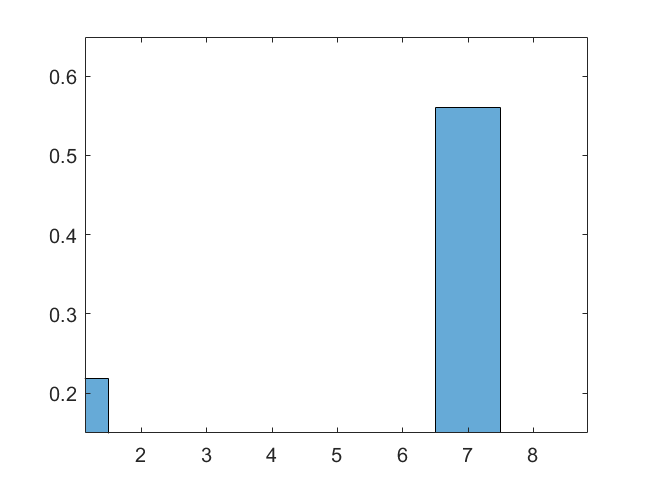

%start=1
%LN(1) = 999;
LN(1) = 99;

LN(2) = N;
[mc,f,w,dw2]=mrkvchain(W,LN,start);
mchistory(mc)


disp(mc(:,end))

     1
     1
     2
     1
     2
     3
     1
     1
     2
     1
     1
     1
     1
     2
     1
     2
     3
     4
     1
     2
     1
     1
     1
     1
     1
     2
     3
     4
     5
     1
     1
     1
     1
     2
     3
     4
     5
     6
     1
     1
     1
     1
     1
     1
     1
     2
     3
     4
     1
     2
     3
     1
     2
     1
     2
     3
     1
     1
     1
     1
     1
     2
     3
     1
     2
     3
     1
     2
     1
     2
     3
     4
     1
     2
     3
     1
     1
     2
     3
     4
     5
     6
     7
     7
     7
     7
     7
     7
     7
     7
     7
     7
     7
     7
     7
     7
     7
     7
     7
     7



% 10 storie di Markov
disp(mc)

  Columns 1 through 10

     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     1     1     1     2     2
     1     3     3     1     3     1     1     2     3     3
     1     1     4     2     1     2     1     1     1     1
     1     1     5     1     2     3     1     1     2     2
     2     2     1     1     1     4     1     2     3     3
     1     1     1     2     1     1     2     3     1     1
     1     1     1     1     1     2     3     4     2     1
     1     2     2     2     2     1     1     1     1     2
     2     1     3     3     3     2     2     2     2     3
     1     2     1     4     1     1     3     1     3     4
     1     1     2     1     1     2     1     1     1     1
     1     1     1     2     1     3     1     2     2     2
     1     1     1     3     2     4     1     1     3     1
     2     2     2     1     3     1     2     1     1     1
     1     1     3     2     4     2     1     2     2     1


[u,e]=eig((W));
abs(diag(e))

ans =                          1
         0.991791421712163
         0.420154549170266
         0.427360196738417
         0.427360196738417
         0.453107481906339
         0.453107481906339


%eigs usa altri algs per calcolare autovalori:sparse eig
%eigs(W,3)
%start = [1 1 1 1 1 1 1 1 1 1];
%u sono gli autovettori corrispondenti agli autovalori

%lo stato corrispondente all'equilibrio statistico è l'autovettore di w
%con autovalore 1 
u(:,1)

ans =      0
     0
     0
     0
     0
     0
     1


sum(u(:,1)) 

ans =      1


%la normalizzazione non è quella corretta perchè eig da normalizzazione rispetto
%a L2, cioè la somma dei moduli quadri fa 1;
%io voglio che questo stato sia una probabilità, cioè che sia normalizzato e
%con tutte entrate positive; ma il set ergodico è quello senza gli stati
%transienti e quindi su tutto i set ergodico per tutti gli altri nodi ho
%numeri positivi.
p = u(:,1)/sum(u(:,1))

p =      0
     0
     0
     0
     0
     0
     1


%p=(u(:,1))
sum(p)

ans =      1


%con cosa lo confronto ?

We can confront the value obtained by diagonalizing the stochastich matrix with the distribution of states gained by the histogram

We can confront the two histcounts, the vertical and horizontal to check that: the distribution of states of a single sory tends to be  the distriution of states along all the story.

c=histcounts(mc,'Normalization','probability')

c =                    0.35351                   0.17622                   0.08783                   0.04358                   0.02195                   0.01103                   0.30588


[p c'] 

ans =                          0                   0.35351
                         0                   0.17622
                         0                   0.08783
                         0                   0.04358
                         0                   0.02195
                         0                   0.01103
                         1                   0.30588


c1=histcounts(mc(:,LN(2)),'Normalization','probability')

c1 =                       0.41                      0.18                      0.12                      0.06                      0.03                      0.02                      0.18


cv=c1; clear c1
ch=histcounts(mc(end,:),'Normalization','probability')

ch =                      0.219                     0.092                     0.071                     0.031                     0.021                     0.006                      0.56


[p c' cv'] %vertical histogram vs a lot of stories

ans =                          0                   0.35351                      0.41
                         0                   0.17622                      0.18
                         0                   0.08783                      0.12
                         0                   0.04358                      0.06
                         0                   0.02195                      0.03
                         0                   0.01103                      0.02
                         1                   0.30588                      0.18


[p c' ch']

ans =                          0                   0.35351                     0.219
                         0                   0.17622                     0.092
                         0                   0.08783                     0.071
                         0                   0.04358                     0.031
                         0                   0.02195                     0.021
                         0                   0.01103                     0.006
                         1                   0.30588                      0.56


qualche appunto sul calcolo delle frequenze con mrkvchain.m

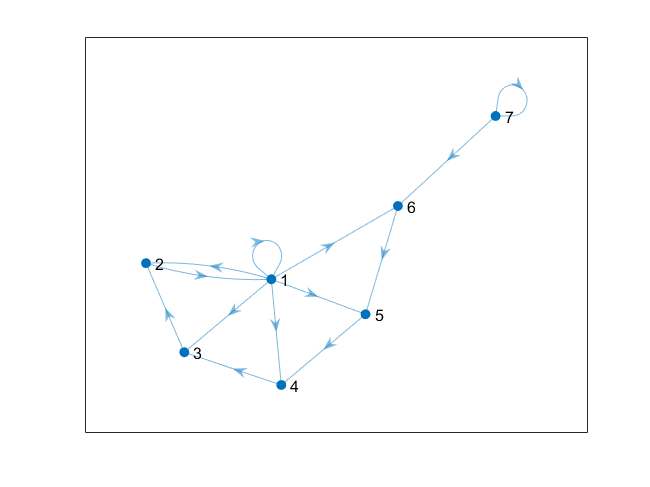

%%
%posso costruire un grafo 
%disp(f)
g=digraph(W);
plot(g)


%perform a randomwalk through the chain
%rwalkongraph(g)
%disp(f(7,:))

We can look at the relative frequence for 7th state in the random walk through histogram using rel. frequence matrix

%mean(f(7,:))
Step=zeros(1,LN(2));
Freq=zeros(1,LN(2));
  
for k=1:LN(2)
    freq=0;
    for j=1:LN(1)

        if mc(j,k) == 7
            freq = freq+1; 
            
        end
        
    end
     Freq(k) = freq ;
     Step(k) =(99-freq);
end

%disp(Freq)
%numero di storie in cui non è stato raggiunto il settimo stato
negative_story=0;
for i=1:length(Freq)
    if Freq(1,i)==0
        negative_story=negative_story+1;
    end
end
positive_story=N-negative_story;


%disp(mean(Freq)) %average step before reaching the seventh state


mchistory.m might be usefull to see the evolution of the 1e3 Markov stories; it gives the evolution in t of the orizonthal histo (i.e. the marginal pdf), the same is done using histogram(...).

In the limit of an infinite number of stories is the evolution of the probability according to Chatman-Kolmogorov evolution equation.

${P_j \left(t\right)} =\sum_k W_{\mathrm{jk}}^t P_k \left(0\right)$ where W is the stochastich matrix of the markovian process.

My solution is to set up a margov chain which has 2 ergodic subsets: 

- the first subset is made up of nodes (0,1,2,3,4,5)

- the second subset is made up of state 6

Once the random walker (a single story) arrives in the seventh state, which is itself an ergodic subset, it remains there; like for the decay model the seventh is a decaded state (a well state).

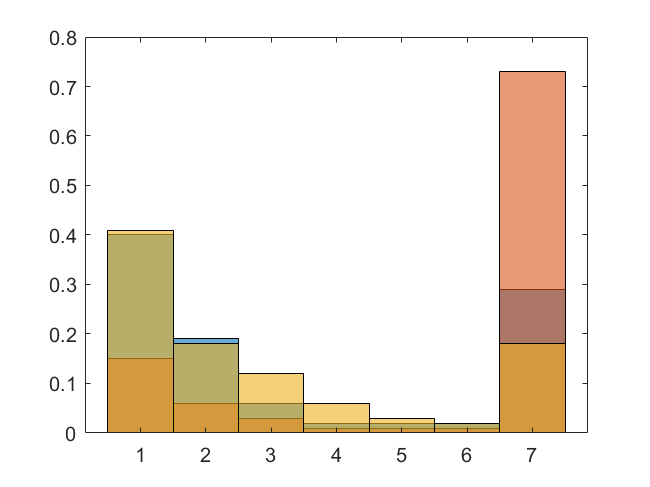

histogram(mc(:,289),'Normalization','probability')
hold on
histogram(mc(:,700),'Normalization','probability')
hold on
histogram(mc(:,1000),'Normalization','probability')